# Interpolation

wiki: [https://en.wikipedia.org/wiki/Interpolation](https://en.wikipedia.org/wiki/Interpolation)

distinguish between

- function approximation: [https://en.wikipedia.org/wiki/Function_approximation](https://en.wikipedia.org/wiki/Function_approximation)

- curve fitting: [https://en.wikipedia.org/wiki/Curve_fitting#Functions](https://en.wikipedia.org/wiki/Curve_fitting#Functions)

## parameter

num_data = 5;
data_x = linspace(0,1,num_data);
data_y = rand(size(data_x));

num_interp_x = 100;
interp_x = linspace(0,1,num_interp_x);

## built-in

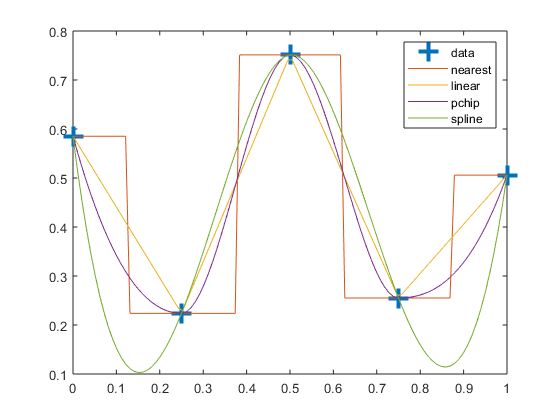

fig = figure();
ax = axes(fig, 'NextPlot','add','Box','on');
hline0 = plot(ax, data_x, data_y, 'LineStyle', 'none', 'Marker', '+', 'MarkerSize', 15,'LineWidth',3);

tmp1 = interp1(data_x, data_y, interp_x, 'nearest'); %doc('interp1')
hline1 = plot(ax, interp_x, tmp1);

tmp1 = interp1(data_x, data_y, interp_x, 'linear');
hline2 = plot(ax, interp_x, tmp1);

tmp1 = interp1(data_x, data_y, interp_x, 'pchip');
hline3 = plot(ax, interp_x, tmp1);

tmp1 = interp1(data_x, data_y, interp_x, 'spline');
hline4 = plot(ax, interp_x, tmp1);

legend([hline0,hline1,hline2,hline3,hline4],{'data', 'nearest', 'linear', 'pchip','spline'})

## Lagrangian

wiki: [https://en.wikipedia.org/wiki/Lagrange_polynomial](https://en.wikipedia.org/wiki/Lagrange_polynomial)

formula:

- 
$$$$
p_k\left( x \right) =\frac{\left( x-x_0 \right) ...\left( x-x_{k-1} \right) \left( x-x_{k+1} \right) ...\left( x-x_N \right)}{\left( x_k-x_0 \right) ...\left( x_k-x_{k-1} \right) \left( x_k-x_{k+1} \right) ...\left( x_k-x_N \right)}
$$
$$


- 
$$$$
p_i\left( x_k \right) =\delta _{ik}
$$
$$


- 
$$$$
L\left( x \right) =\sum_i{p_i\left( x \right) f_i}
$$
$$


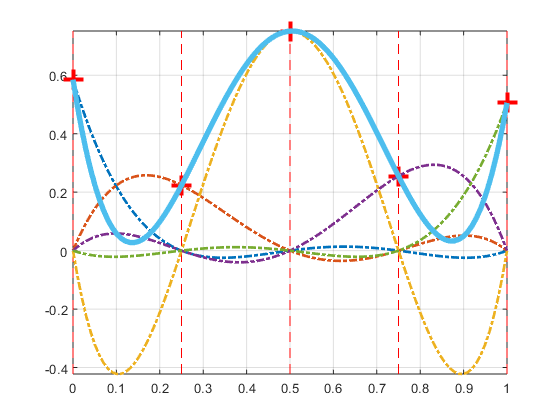

interp_y = zeros(num_data, num_interp_x);

for ind1 = 1:num_data
    tmp1 = data_x([1:(ind1-1),(ind1+1):num_data]);
    interp_y(ind1,:) = prod(interp_x - tmp1',1)/prod(data_x(ind1)-tmp1)*data_y(ind1);
end

fig = figure();
ax = axes(fig, 'NextPlot','add','Box','on');
ylim_min = min(min(sum(interp_y,1)), min(interp_y(:)));
ylim_max = max(max(sum(interp_y,1)), max(interp_y(:)));
ax.XLim = [min(interp_x), max(interp_x)];
ax.YLim = [ylim_min,ylim_max];
grid(ax, 'on')
ax.Title.FontSize = 20;
hLine = gobjects(1,num_data+1);

hLine_data = line(data_x,data_y,'LineStyle','None',...
    'Marker','+','LineWidth',3,'Color',[1,0,0],'MarkerSize',15);
for ind1 = 1:num_data
    line([data_x(ind1),data_x(ind1)],ax.YLim,'LineStyle','--','Color',[1,0,0]);
end

for ind1 = 1:num_data
    hLine(ind1) = plot(interp_x,interp_y(ind1,:),'LineWidth',2,'LineStyle','-.');
end
hLine(end) = plot(interp_x,sum(interp_y,1),'LineWidth',4);

## Neville interpolation

wiki: [https://en.wikipedia.org/wiki/Neville%27s_algorithm](https://en.wikipedia.org/wiki/Neville%27s_algorithm)

formula

- 
$$$$
p_{ii}\left( x \right) =f_i
$$
$$


- 
$$$$
p_{ij}\left( x \right) =\frac{\left( x_i-x \right) p_{i+1j}\left( x \right) +\left( x-x_j \right) p_{ij-1}\left( x \right)}{x_i-x_j}
$$
$$


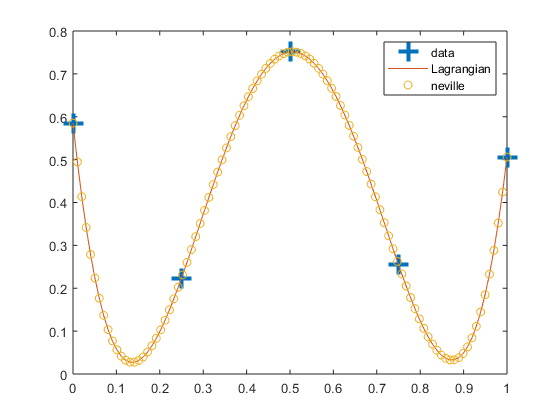

y_lagrangian = my_lagrangian_interpolation(data_x, data_y, interp_x);
y_neville = my_naive_neville(data_x, data_y, interp_x);

fig = figure();
ax = axes(fig, 'NextPlot','add','Box','on');
hline0 = plot(ax, data_x, data_y, 'LineStyle', 'none', 'Marker', '+', 'MarkerSize', 15,'LineWidth',3);
hline1 = plot(ax, interp_x, y_lagrangian);
hline2 = plot(ax, interp_x, y_neville, 'o');
legend([hline0,hline1,hline2], {'data', 'Lagrangian', 'neville'})

## function

function y = my_lagrangian_interpolation(x0, y0, x)
% reference: https://en.wikipedia.org/wiki/Lagrange_polynomial
% x0(1,N0) y0(1,N0) x(1,N1) y(1,N1)
N0 = size(x0,2);
y = zeros(1, size(x,2));

for ind1 = 1:N0
    tmp1 = x0([1:(ind1-1),(ind1+1):N0]);
    y = y + prod(x- tmp1',1)/prod(x0(ind1)-tmp1',1)*y0(ind1);
end
end

function y = my_naive_neville(x0, y0, x)
% reference: https://en.wikipedia.org/wiki/Neville%27s_algorithm
% x0(1,N0) y0(1,N0) x(1,N1) y(1,N1)
% not available until 20181025
end
